clc; clear; close all;
filename = "Five_times_Kinematics_HT_Query_QUadratic.xlsx";
data = readtable(filename);

%Seleccionamos columnas numéricas
isNum = varfun(@isnumeric, data, 'OutputFormat', 'uniform');
numericData = data(:, isNum);
X = table2array(numericData);
[n, p] = size(X);
fprintf('El dataset tiene %d observaciones y %d variables numéricas.\n', n, p);

El dataset tiene 50 observaciones y 239 variables numéricas.


Normalizamos los datos, para estandarizar las columnas

X_norm = normalize(X);

Realizamos PCA de los datos normalizados

[coeff, score, latent, tsquared, explained, mu] = pca(X_norm);

Obtenemos la siguiente información:

- `coeff`: Vectores propios (direcciones principales).

- `score`: Proyecciones de los datos sobre los nuevos ejes.

- `latent`: Valores propios (varianzas de cada componente).

- `explained`: Porcentaje de varianza explicado por cada componente.

La varianza acumulada que queremos tener es de 80%, para ello tenemos que seleccionar un número mínimo de componentes que expliquen dicha varianza.

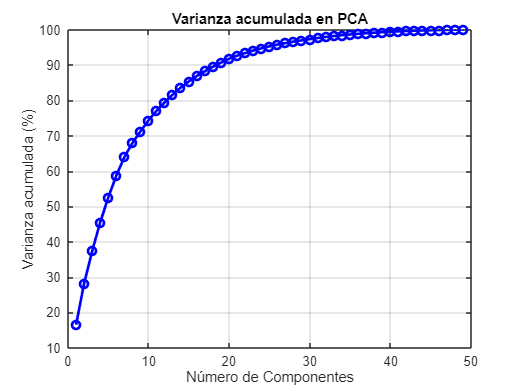

cumulativeExplained = cumsum(explained);

plot(cumulativeExplained, 'bo-', 'LineWidth', 2);
xlabel('Número de Componentes');
ylabel('Varianza acumulada (%)');
title('Varianza acumulada en PCA');
grid on;


numComponents = find(cumulativeExplained >= 80, 1, 'first');
fprintf('Número de componentes que explican el 80%% de la varianza: %d\n', numComponents);

Número de componentes que explican el 80% de la varianza: 13


figure;

Con 13 componentes somos capaces de explicar el 80% de la varianza de nuestros datos

Una vez tenemos la varianza acumula, procedemos a calcular PCs significativos

covX = cov(X_norm);
[V, D] = eig(covX);
eigvals = diag(D);
% Ordenar en orden descendente
[eigvals_sorted, idx] = sort(eigvals, 'descend');
% También se pueden reordenar los eigenvectores si se necesita:
V_sorted = V(:, idx);

fprintf('Eigenvalores observados (ordenados descendente):\n');

Eigenvalores observados (ordenados descendente):


disp(eigvals_sorted');

   39.5444   28.0384   21.9468   19.4087   16.7453   14.8539   12.4924    9.4906    7.8811    7.4453    6.4654    5.5949    5.3034    4.7123    4.0902    3.7518    3.2721    3.0055    2.7520    2.5640    2.1106    1.7442    1.7083    1.4879    1.3000    1.1884    1.0377    0.9596    0.8655    0.8326    0.7457    0.7189    0.6265    0.5454    0.4895    0.4400    0.3931    0.3635    0.3372    0.3019    0.2814    0.2188    0.1834    0.1733    0.1544    0.1425    0.1135    0.1062    0.0714    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


%% Prueba de permutación usando eig
num_permutations = 1000;
permuted_eigenvalues = zeros(num_permutations, p);

for i = 1:num_permutations
    % Permutar de forma independiente cada columna de X_norm
    X_perm = X_norm;
    for j = 1:p
        X_perm(:, j) = X_perm(randperm(n), j);
    end
    % Calcular la matriz de covarianza de los datos permutados
    covX_perm = cov(X_perm);
    % Calcular eigenvalores usando eig
    [~, D_perm] = eig(covX_perm);
    eigvals_perm = diag(D_perm);
    % Ordenar en forma descendente
    [eigvals_perm_sorted, ~] = sort(eigvals_perm, 'descend');
    % Almacenar los eigenvalores ordenados en la iteración i
    permuted_eigenvalues(i, :) = eigvals_perm_sorted';
end

%% Calcular p-values para cada componente
% Para cada componente, el p-valor es la proporción de permutaciones en las que
% el eigenvalor permutado es mayor o igual que el eigenvalor observado.
p_values = zeros(1, p);
for i = 1:p
    p_values(i) = sum(permuted_eigenvalues(:, i) >= eigvals_sorted(i)) / num_permutations;
end

%% Mostrar resultados
for i = 1:p
    fprintf('Componente %d: Eigenvalor = %.4f, p-value = %.4f\n', i, eigvals_sorted(i), p_values(i));
end

Componente 1: Eigenvalor = 39.5444, p-value = 0.0000
Componente 2: Eigenvalor = 28.0384, p-value = 0.0000
Componente 3: Eigenvalor = 21.9468, p-value = 0.0000
Componente 4: Eigenvalor = 19.4087, p-value = 0.0000
Componente 5: Eigenvalor = 16.7453, p-value = 0.0000
Componente 6: Eigenvalor = 14.8539, p-value = 0.0000
Componente 7: Eigenvalor = 12.4924, p-value = 0.0000
Componente 8: Eigenvalor = 9.4906, p-value = 0.0000
Componente 9: Eigenvalor = 7.8811, p-value = 0.0000
Componente 10: Eigenvalor = 7.4453, p-value = 0.0010
Componente 11: Eigenvalor = 6.4654, p-value = 1.0000
Componente 12: Eigenvalor = 5.5949, p-value = 1.0000
Componente 13: Eigenvalor = 5.3034, p-value = 1.0000
Componente 14: Eigenvalor = 4.7123, p-value = 1.0000
Componente 15: Eigenvalor = 4.0902, p-value = 1.0000
Componente 16: Eigenvalor = 3.7518, p-value = 1.0000
Componente 17: Eigenvalor = 3.2721, p-value = 1.0000
Componente 18: Eigenvalor = 3.0055, p-value = 1.0000
Componente 19: Eigenvalor = 2.7520, p-value = 1.


alpha_perm = 0.01;
significant_PCs = find(p_values < alpha_perm);
fprintf('Componentes significativos (p < %.2f): ', alpha_perm);

Componentes significativos (p < 0.01): 

fprintf('%d ', significant_PCs);

1 2 3 4 5 6 7 8 9 10 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 72 73 74 75 76 77 78 79 80 81 82 83 85 90 96 97 98 99 100 123 

fprintf('\n');

Esta prueba  indica que únicamente los primeros 10 componentes son significativamente mayores de lo que se esperaría por azar. Esto sugiere que la estructura relevante del conjunto de datos está contenida en esos 10 primeros PCs, y que los componentes subsiguientes probablemente capturan varianza que puede atribuirse al azar (ruido).

**Análisis MANOVA**

ageGroup = data.AgeGroup;
bmiValue = data.BMI_Value;
groupName = data.GroupName;

compositeStr = string(ageGroup) + "_" + string(bmiValue) + "_" + string(groupName);
compositeFactor = categorical(compositeStr);

% Excluir las columnas 2, 3 y 4 para obtener las variables dependientes
allCols = 1:width(data);
colsToKeep = setdiff(allCols, [2, 3, 4]);
Y = table2array(data(:, colsToKeep));
[n_dep, p_dep] = size(Y);
fprintf('El MANOVA usará %d observaciones y %d variables dependientes.\n', n_dep, p_dep);

El MANOVA usará 50 observaciones y 239 variables dependientes.



%% Reducir dimensionalidad de las variables dependientes usando PCA
% Normalizamos las variables dependientes
Y_norm = normalize(Y);
[coeff_Y, score_Y, latent_Y, ~, explained_Y] = pca(Y_norm);

% Por ejemplo, retener el número mínimo de componentes que expliquen al menos el 80% de la varianza
cumulativeExplained_Y = cumsum(explained_Y);
numComponents_Y = find(cumulativeExplained_Y >= 80, 1, 'first');
fprintf('Retenemos %d componentes para explicar el 80%% de la varianza en Y.\n', numComponents_Y);

Retenemos 13 componentes para explicar el 80% de la varianza en Y.



% Usamos los scores de PCA como nuevas variables dependientes para MANOVA
Y_reduced = score_Y(:, 1:numComponents_Y);

%% Realizar MANOVA con los componentes retenidos
[d_manova, table_manova, stats] = manova1(Y_reduced, compositeFactor);

disp('Resultados del análisis MANOVA (usando PCA en Y):');

Resultados del análisis MANOVA (usando PCA en Y):


disp(table_manova);

    0.0816
    0.5330
    0.8759
    0.9958
    0.9988
    0.9999
    0.9994




pValue_MANOVA = table_manova(end, end);
fprintf('Valor p del MANOVA (factor compuesto con Y reducido): %.4f\n', pValue_MANOVA);

Valor p del MANOVA (factor compuesto con Y reducido): 0.9994


abstract mode

A

Age = data{:, 'AgeGroup'};
BMI = data{:, 'BMI_Value'};
Therapy = data{:, 'GroupName'};

% Convertir a categorical (si aún no lo son)
Age = categorical(Age);
BMI = categorical(BMI);
Therapy = categorical(Therapy);

allCols = 1:width(data);
colsToKeep = setdiff(allCols, [2, 3, 4]);
X = table2array(data(:, colsToKeep));
[n, p] = size(X);
fprintf('El dataset usado para PCA tiene %d observaciones y %d variables.\n', n, p);

El dataset usado para PCA tiene 50 observaciones y 239 variables.



PCs = score(:, 1:6);
cumulativeExplained = sum(explained(1:6));
fprintf('Los primeros 6 PCs explican %.2f%% de la varianza.\n', cumulativeExplained);

Los primeros 6 PCs explican 58.80% de la varianza.
